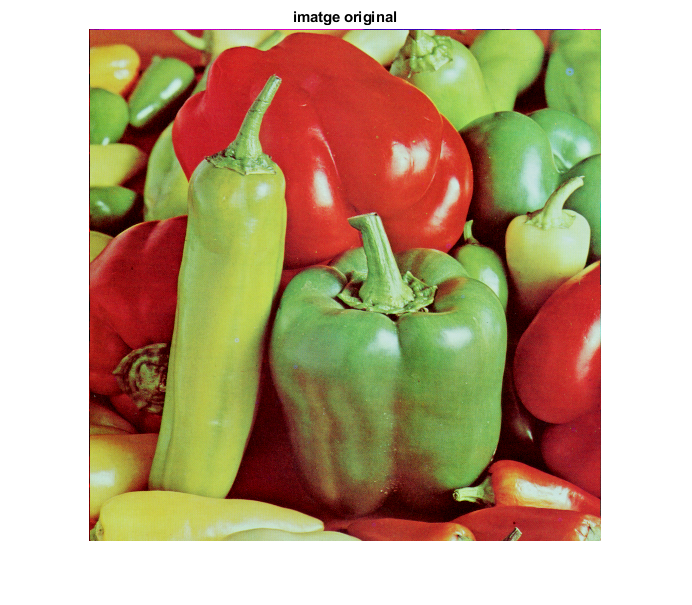

im=imread('peppers.png');
[MAXFILA MAXCOL chan]=size(im);
figure,imshow(im),title('imatge original')


% la segmentarem per color. Treballarem en l'espai Hue-Sat
hsv=rgb2hsv(im);
hs=hsv(:,:,1:2);

vect=reshape(hs,MAXFILA*MAXCOL,2);
[m,n] = size(vect);
nClusters = 3;
vectClusters = zeros(1,nClusters,'double');
vectGroups = zeros(m,1,'uint8');
for i=1:nClusters
    aux = rand;
    vectClusters(i) = rand * m;
end

